%load the data
folder = "D:\Whale Data\Raw Audio Data\CaseyIslands2017";
dsname = "CaseyIslands2017";
data = load(folder + "\features\features.mat").data;

fb = load(folder + "\scattering\filterbank.mat").fb;


%prepare the data
X = data{:, "Features"};
X = double(X);
y = data{:, "Annotation"};
groupcounts(data, "Annotation")

ans = 9×3 table
         Annotation         GroupCount    Percent 
    ____________________    __________    ________

    "Bm_Ant-A"                 1914         6.8859
    "Bm_Ant-B"                  581         2.0902
    "Bm_Ant-Z"                  179        0.64398
    "Bm_D"                      288         1.0361
    "Bp_20Hz"                     5       0.017988
    "Bp_20Plus"                  42         0.1511
    "Multiple"                   93        0.33458
    "Noise"                   24488         88.099
    "Unidentified_calls"        206        0.74111


y = replace(y, "-", "_");
y(~contains(y, "Bm_Ant_Z")) = "Noise";
y(contains(y, "Bm_D")) = "Noise";
idx = contains(y, "Bm") | y == "Noise";
% idx = contains(y, "Bm") | y == "Noise" | contains(y, "Bp_20Plus");
idx = idx & all(~isnan(X), 2);
y = y(idx);

f_idx = find(fb.filterBanks(1).fc > 40 & fb.filterBanks(1).fc < 110);
s2_idx = fb.pathstart(f_idx(1)+1) + (0:sum(fb.pathsizes(f_idx(1)+1:f_idx(end)))-1);
select = [f_idx, s2_idx];
X = X(idx, [1:end-1, end]);

unique(y)

ans = 2×1 string array
    "Bm_Ant_Z"
    "Noise"


Xn = ((X-mean(X, 1))./std(X, 1));



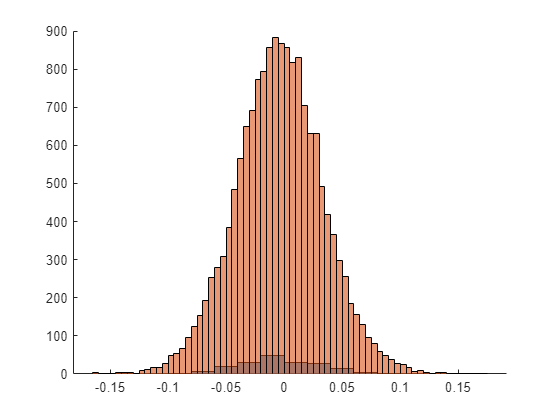

figure
hold on
histogram(X(y ~= "Noise", end)/2.04)
histogram(X(y == "Noise", end)/2.04)
hold off

%split the data
ynoiseidx = find(y == "Noise");
ysigidx = find(y ~= "Noise");
idxnoise = splitlabels(y(ynoiseidx), 2000, "randomized");
idxsignal = splitlabels(y(ysigidx), 0.8, "randomized");
idxs{1} = [ynoiseidx(idxnoise{1}); ysigidx(idxsignal{1})];
idxs{2} = [ynoiseidx(idxnoise{2}); ysigidx(idxsignal{2})];

idxsignal

idxsignal = 2×1 cell array
    {608×1 double}
    {152×1 double}


idxnoise

idxnoise = 2×1 cell array
    { 2000×1 double}
    {24690×1 double}



Xtrain = Xn(idxs{1}, :);
ytrain = y(idxs{1}, :);
Xtest = Xn(idxs{2}, :);
ytest = y(idxs{2}, :);

sweep(Xn, y, 0.65, 0.85);

Elapsed time is 0.123863 seconds.


noiseps = linspace(0.01, 0.9, 8);
gammas = linspace(0.2, 1, 8);
C = numel(unique(y));
cm = zeros(C, C, numel(noiseps), numel(gammas));
cmss = cm;
sigvsnoise = zeros(2, 2, numel(noiseps), numel(gammas));
score = zeros(numel(noiseps), numel(gammas));
N = 6;
parfor i = 1:N
    i
    [cmt, sigvsnoiset, scoret] = sweep(Xn, y, noiseps, gammas);
    cm = cm + cmt/N;
    sigvsnoise = sigvsnoise + sigvsnoiset/N;
    score = score + scoret/N;
end


ans =

     1


ans =

     2


ans =

     3


ans =

     4


ans =

     5


ans =

     6

Elapsed time is 22.907012 seconds.
Elapsed time is 22.856046 seconds.
Elapsed time is 23.078864 seconds.
Elapsed time is 23.111291 seconds.
Elapsed time is 22.973795 seconds.
Elapsed time is 22.860860 seconds.


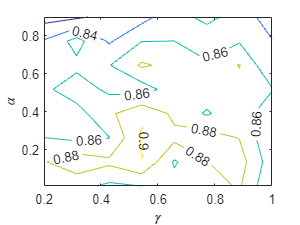

figure
contour(gammas, noiseps , score, 0.5:0.02:0.95, "ShowText","on")
xlabel("\gamma")
ylabel("\alpha")
zlabel("Average Accuracy")

[mscore, midx] = max(score, [], "all");
[aidx, gammaidx] = ind2sub(size(score), midx);
fprintf("Max score of %.2f with parameters a=%.2f and gamma=%.2f", mscore * 100, noiseps(aidx), gammas(gammaidx))

Max score of 90.26 with parameters a=0.26 and gamma=0.54

svnbest = sigvsnoise(:, :, aidx, gammaidx);
svnbestnorm = svnbest./sum(svnbest, 2);
cmbest = cm(:, :, aidx, gammaidx);
fprintf("Resulting accuracies of %.2f and %.2f", svnbestnorm(1,1), svnbestnorm(2,2))

Resulting accuracies of 0.93 and 0.88

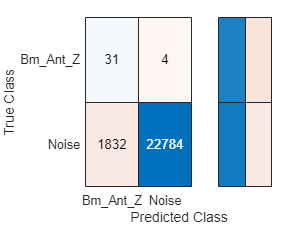


figure
confusionchart(floor(cmbest), sort(unique(y), 1, "descend"), "RowSummary", "row-normalized")

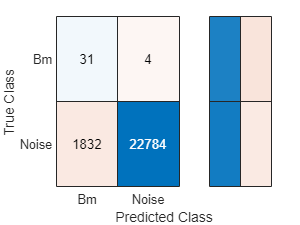

figure
confusionchart(floor(svnbest),["Noise", "Bm"], "RowSummary", "row-normalized")

function [Xtrain, ytrain, Xtest, ytest] = split(Xn, y)
ynoiseidx = find(y == "Noise");
ysigidx = find(y ~= "Noise");
idxnoise = splitlabels(y(ynoiseidx), 3000, "randomized");
idxsignal = splitlabels(y(ysigidx), 0.8, "randomized");
idxs{1} = [ynoiseidx(idxnoise{1}); ysigidx(idxsignal{1})];
idxs{2} = [ynoiseidx(idxnoise{2}); ysigidx(idxsignal{2})];
Xtrain = Xn(idxs{1}, :);
ytrain = y(idxs{1}, :);
Xtest = Xn(idxs{2}, :);
ytest = y(idxs{2}, :);
end

function [cm, sigvsnoise, score] = sweep(Xn, y, noiseps, gammas)
tic
C = numel(unique(y));
cm = zeros(C, C, numel(noiseps), numel(gammas));
sigvsnoise = zeros(2, 2, numel(noiseps), numel(gammas));
score = zeros(numel(noiseps), numel(gammas));
for i = 1:numel(noiseps)
    noisep = noiseps(i);
    for j = 1:numel(gammas)
        gamma = gammas(j);
%         sigp = (1- noisep)/3;
%         prior = struct("Bm_Ant_A",sigp, "Bm_Ant_B", sigp, "Bm_Ant_Z",sigp, "Noise", noisep);
%         sigp = (1- noisep)/4;
%         prior = struct("Bm_Ant_A",sigp, "Bm_Ant_B", sigp, "Bm_Ant_Z",sigp, "Bm_D", sigp, "Noise", noisep);
        sigp = (1- noisep);
        prior = struct("Bm_Ant_A",sigp,"Bm_Ant_B",sigp,"Bm_Ant_Z",sigp,"Bm_Ant",sigp, "Bm_D", sigp, "Bp_20Plus", sigp, "Noise", noisep);
        cls = Discriminant(gamma, "linear", 0);
        [Xtrain, ytrain, Xtest, ytest] = split(Xn, y);
        cls.fit(Xtrain, ytrain, prior);
        yhat = cls.predict(Xtest);
        [c, order] = confusionmat(ytest, yhat);
        [order, sidx] = sort(order, 1, "descend");
        c = c(sidx, sidx);
        cm(:, :, i, j) = c;        
        s = [c(1, 1), sum(c(1, 2:end)); sum(c(2:end, 1)), sum(c(2:end, 2:end), 'all')];
        sigvsnoise(:, :, i, j) = s;
        snorm = s./sum(s, 2);
%         score(i, j) = mean(diag(c./sum(c, 2)));
        score(i, j) = mean(diag(snorm));
    end
end
toc
end